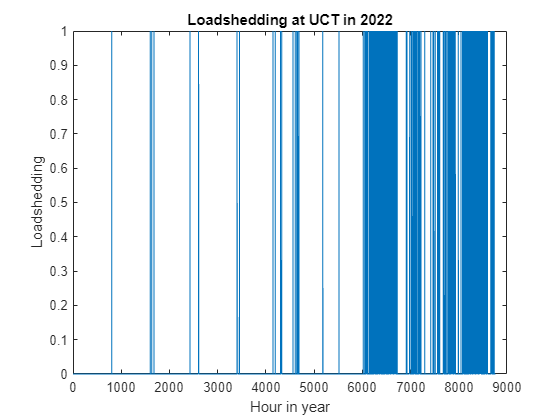

data = readtable("loadShedding2022.csv");

figure
plot(data.LoadShedding)
title("Loadshedding at UCT in 2022")
ylabel("Loadshedding")
xlabel("Hour in year")

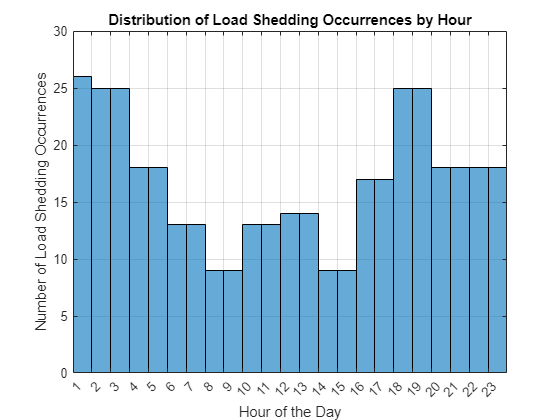




% Number of hours in a year
numHours = 8760;

% Generate hours of the day based on row index
hoursOfDay = mod(0:(numHours-1), 24);

dummy = data.LoadShedding(:);

for i = 1:8760
    if dummy(i)
        data.LoadShedding(i+1)=1;
    end
end 
% Plot histogram for LoadShedding occurrences based on hour of the day
figure;
histogram(hoursOfDay(data.LoadShedding > 0), 0:24); % Assuming > 0 means load shedding occurred
xlabel('Hour of the Day');
ylabel('Number of Load Shedding Occurrences');
title('Distribution of Load Shedding Occurrences by Hour');
xticks(0:1:23); % To make it clear that it's hourly data
xlim([1 24])
grid on;




pv_data = readtable("BNKJUL001_Thesis_solarGen500kWHomer.csv")
wind_data = readtable("BNKJUL001_Thesis_Wind500kGenHomer.csv")






